# The three most important equations in neural time series data analysis

[mikeXcohen@gmail.com](mailto:mikeXcohen@gmail.com)

## sine wave

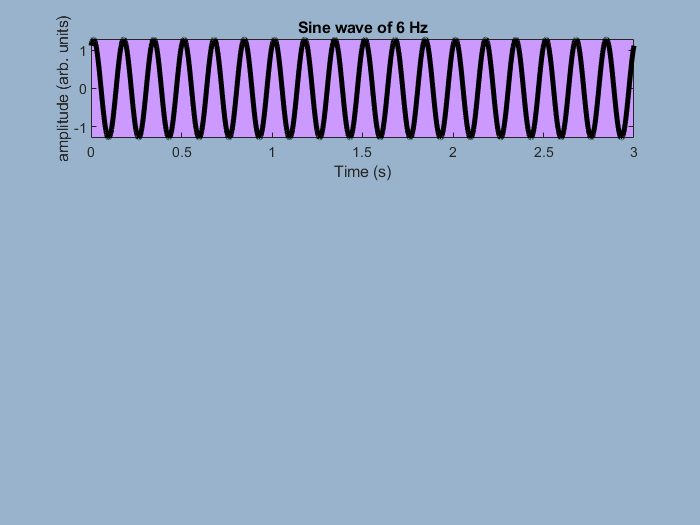

% frequency of sine wave in Hz
freq  = 6;
ampl  = 1.3; % amplitude, in arbitrary units
phas  = pi/3;

srate = 1000; % in hz, thus 1-ms resolution
time  = 0:1/srate:3;

figure(1), clf
set(gcf,'color',[.6 .7 .8])

subplot(311)
plot(time,ampl*sin(2*pi*freq.*time + phas),'k','linewidth',3)
set(gca,'color',[.8 .6 1])
xlabel('Time (s)'), ylabel('amplitude (arb. units)')
title([ 'Sine wave of ' num2str(freq) ' Hz' ])

## Gaussian curve

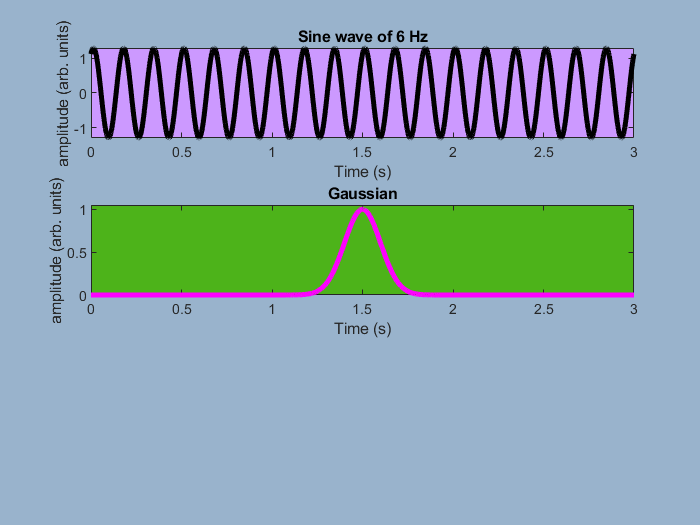

width = .1;
peaktime = 1.5; % in seconds

subplot(312)

plot(time,exp( (-(time-peaktime).^2) / (2*width^2) ),'m','linew',3)
set(gca,'ylim',[0 1.05],'color',[.3 .7 .1])
xlabel('Time (s)'), ylabel('amplitude (arb. units)')
title('Gaussian')

## Euler's formula

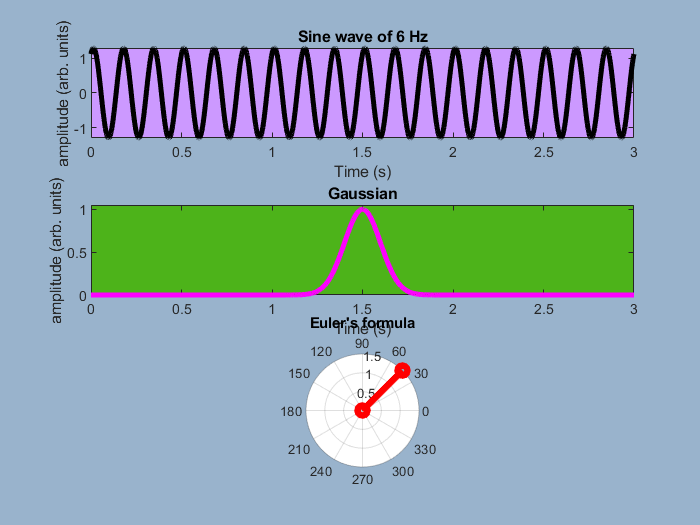

m = 1.5;
k = pi/4;

euler = m*exp(1i*k);

subplot(3,3,8)
%h= polar([0 angle(euler)],[0 abs(euler)],'r-o');
h= polarplot([0 angle(euler)],[0 abs(euler)],'r-o');
set(h,'linew',4)
title('Euler''s formula')

## end.